# Tutorial 3 - EEG: from scalp to sources

In this tutorial, we will give an overview of the preprocessing steps to project the scalp EEG data into the source space and resume them at the level of regions of interest (ROIs) using [Fieldtrip](https://www.fieldtriptoolbox.org/). To do so we will you the first subject of the VEPCON: [https://openneuro.org/datasets/ds003505/versions/1.0.2](https://openneuro.org/datasets/ds003505/versions/1.0.2) described in: [https://doi.org/10.1101/2021.03.16.435599](https://doi.org/10.1101/2021.03.16.435599)

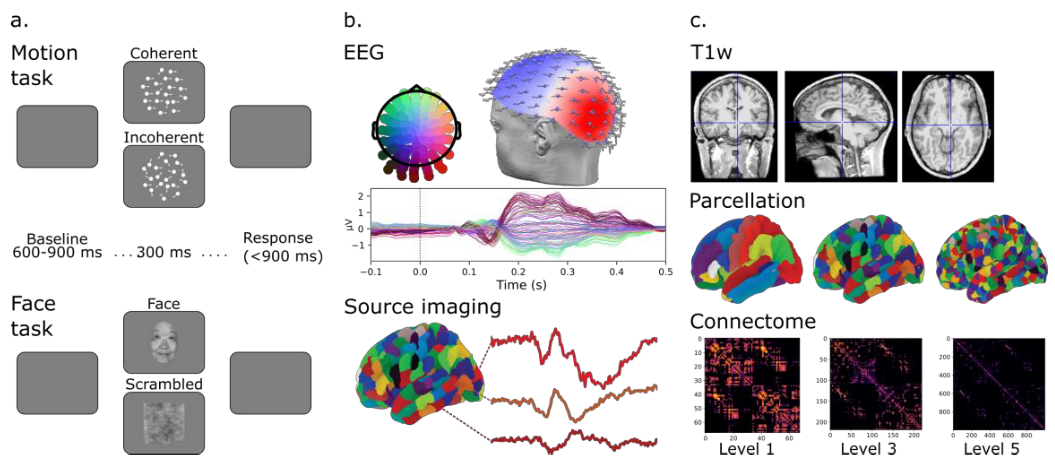

## Initialisation

try
    system('git stash --include-untracked') % store the modification in the stash
    system('git pull https://github.com/sinergia-connectomics-summerschool-2021/tutorial03-code.git') % pull the newest version of the repository to be sure to be up-to-date
catch
    warning('Did not manage to pull the latest version of the code from Github')
end
addpath(genpath('.'))% make sure Matlab's current path in Tutorial 3 folder in the code folder of the datatest
BIDS_folder = fullfile('/', 'home','sinergiasummerschool','Data','ds003505'); 
path2fieldtrip = fullfile('/', 'home', 'sinergiasummerschool', 'Softwares', 'fieldtrip');
addpath(path2fieldtrip);  % add Fieldtrip to the Matlab path
ft_defaults % this initialise Fieldtrip (/!\ do not initialise Fieldtrip with a recursive addpath [ addpath(genpath(path2fieldtrip)) ]
sub_number = 1;
task='task-faces';
ft_warning off% Fieldtrip tends to raise a lot of warning, these are disabled otherwise it would make this tutorial cumbersome

## EEG Preprocessing

### Initialisation

sub_id = sprintf('sub-%02d',sub_number);

filename = fullfile(BIDS_folder, sub_id,'eeg', [sub_id,'_',task,'_eeg.bdf']); %eeg file in BIDs 
event_file=fullfile(BIDS_folder, sub_id,'eeg', [sub_id,'_',task,'_events.tsv']); %event file
elec_file=fullfile(BIDS_folder, sub_id,'eeg', [sub_id,'_electrodes.tsv']); %electrode file
eeg_derivatives_path = fullfile(BIDS_folder,'derivatives','eeg_preprocessing',sub_id,'eeg');
load('elec.mat', "elec_proj");

% Tell Datalad to allow files to be modified
if exist(eeg_derivatives_path, 'dir')
    [status,cmdout] = system('datalad unlock -d '+convertCharsToStrings(BIDS_folder)+' '+ convertCharsToStrings(eeg_derivatives_path));
    sprintf(cmdout)
end


ans =

  1×0 empty char array



### Downsampling, filtering and epoching

import the data

cfg = [];
cfg.dataset= filename;
cfg.detrend = 'yes';
data = ft_preprocessing(cfg);

found matching BIDS sidecar '/home/sinergiasummerschool/Data/ds003505/sub-01/eeg/sub-01_task-faces_eeg.json'
reading '/home/sinergiasummerschool/Data/ds003505/sub-01/eeg/sub-01_task-faces_eeg.json'
found matching BIDS sidecar '/home/sinergiasummerschool/Data/ds003505/sub-01/eeg/sub-01_task-faces_channels.tsv'
reading '/home/sinergiasummerschool/Data/ds003505/sub-01/eeg/sub-01_task-faces_channels.tsv'
found matching BIDS sidecar '/home/sinergiasummerschool/Data/ds003505/sub-01/eeg/sub-01_electrodes.tsv'
reading '/home/sinergiasummerschool/Data/ds003505/sub-01/eeg/sub-01_electrodes.tsv'
processing channel { 'A1' 'A2' 'A3' 'A4' 'A5' 'A6' 'A7' 'A8' 'A9' 'A10' 'A11' 'A12' 'A13' 'A14' 'A15' 'A16' 'A17' 'A18' 'A19' 'A20' 'A21' 'A22' 'A23' 'A24' 'A25' 'A26' 'A27' 'A28' 'A29' 'A30' 'A31' 'A32' 'B1' 'B2' 'B3' 'B4' 'B5' 'B6' 'B7' 'B8' 'B9' 'B10' 'B11' 'B12' 'B13' 'B14' 'B15' 'B16' 'B17' 'B18' 'B19' 'B20' 'B21' 'B22' 'B23' 'B24' 'B25' 'B26' 'B27' 'B28' 'B29' 'B30' 'B31' 'B32' 'C1' 'C2' 'C3' 'C4' '

data.elec = elec_proj;

remove STATUS channel and rereference to central chqnnel (A1) to remove CMS contribute

cfg=struct('channel',{data.label(1:end-1)},'reref','yes','refchannel','A1');
data = ft_preprocessing(cfg,data);

the call to "ft_selectdata" took 1 seconds and required the additional allocation of an estimated 2019 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 5 seconds and required the additional allocation of an estimated 2027 MB


Downsample to 250Hz

cfg = struct('resamplefs',250);
data_resamp = ft_resampledata(cfg,data);

the input is raw data with 128 channels and 1 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
resampling data
resampling data in trial 1 from 1

original sampling rate = 2048 Hz
new sampling rate = 250 Hz
the call to "ft_resampledata" took 7 seconds and required the additional allocation of an estimated 2397 MB


keep signal above 1Hz

cfg = struct('hpfilter', 'yes','hpfreq', 1, 'bsfilter','yes','bsfreq',[48 52]);
data_filt = ft_preprocessing(cfg,data_resamp);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 2011 MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 3 seconds and required the additional allocation of an estimated 2012 MB


Read the event files and segment the data and remove bad epochs

% read the events.tsc file and downsample the onset sample and duration which were calculated with the original sampling frequency
[event] = ft_read_event(filename);

found matching BIDS sidecar '/home/sinergiasummerschool/Data/ds003505/sub-01/eeg/sub-01_task-faces_events.tsv'
reading header information from '/home/sinergiasummerschool/Data/ds003505/sub-01/eeg/sub-01_task-faces_eeg.json'



event(isnan([event(:).sample])) = []; 
for evt = 1:length(event)
    event(evt).sample = round(event(evt).sample/data.fsample*250);
    event(evt).duration = round(event(evt).duration/data.fsample*250);
end

% segment the data
% identify trials corresponding to faces (1) and scramble (0) 
% -bad epochs are automatically excluded

cfg.hdr.Fs = 250;
cfg.hdr.nSamples = data_filt.sampleinfo(2);
cfg.hdr.nTrials = 1;
cfg.event = event;
cfg.tracktimeinfo = 'no';
cfg.trialdef.eventtype='FACES';
cfg.trialdef.eventvalue =1;
cfg.trialdef.prestim = 1.5; % in seconds
cfg.trialdef.poststim = 1; % in seconds

[cfg_FAC.trl, cfg_FAC.event] = ft_trialfun_general(cfg);

using the header from the configuration structure
using the events from the configuration structure



cfg.trialdef.eventtype='SCRAMBLED';
cfg.trialdef.eventvalue =0;
[cfg_SCR.trl, cfg_SCR.event] = ft_trialfun_general(cfg);

using the header from the configuration structure
using the events from the configuration structure



% extract trials and exclude trl corresp to 'outliers'
data_seg=segment_trials(cfg_SCR,cfg_FAC,data_filt,event_file,'outliers',1);

the input is raw data with 128 channels and 1 trials
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 124 MB
the input is raw data with 128 channels and 1 trials
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 182 MB
the input is raw data with 128 channels and 294 trials
selecting 293 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 1 MB
concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 4 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 8 MB


### Remove bad channels

read bad channels from *_channels.tsv

chn_filename = strrep(filename,'eeg.bdf','channels.tsv');
chn_tbl = readtable(chn_filename, 'FileType', 'text');
bad_channels = chn_tbl.name(strcmp(chn_tbl.status,'bad'));

Display raw data

the input is raw data with 128 channels and 1 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


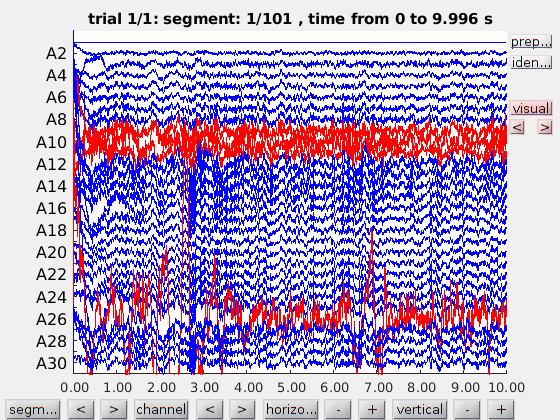

Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.

the call to "ft_databrowser" took 4 seconds and required the additional allocation of an estimated 126 MB


channels_colour = zeros(length(data_filt.label),3);
channels_colour(:,3) = 1;
bln_bad_chn = ismember(data_filt.label,bad_channels);
channels_colour(bln_bad_chn,1) = 1;
channels_colour(bln_bad_chn,3) = 0;

cfg = [];
cfg.layout = 'biosemi128.lay'; 
cfg.viewmode = 'vertical';
cfg.blocksize = 10;
cfg.channel = data_filt.label(1:30);
cfg.ylim = 10*[-1 1];
cfg.continuous='no';
cfg.linecolor = channels_colour;
cfg.allowoverlap='yes';
ft_databrowser(cfg, data_filt)

remove bad channels from the segmented data

good_ch=setdiff(data_seg.label,bad_channels);
cfg = [];
cfg.channel = good_ch;
data_no_bad_ch=ft_selectdata(cfg,data_seg);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 304 MB


### Remove eye blink with ICA

Compute Independent Component Analysis (ICA)

% cfg        = [];
% cfg.method = 'runica';
% cfg.channel = {'all' '-A1'}; % compute ICA using all channels except the A1 which is the new reference
% cfg.updatesens = 'no';
% ICs = ft_componentanalysis(cfg, data_no_bad_ch);

load previously computed ICA decomposition

%% ICA artefact removal
load(fullfile(eeg_derivatives_path,'ica_component.mat'), 'ICs', 'ICs2remove')

plot the independent components

reading layout from file biosemi128.lay
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is component data with 109 components and 109 original channels
the input is raw data with 109 channels and 587 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


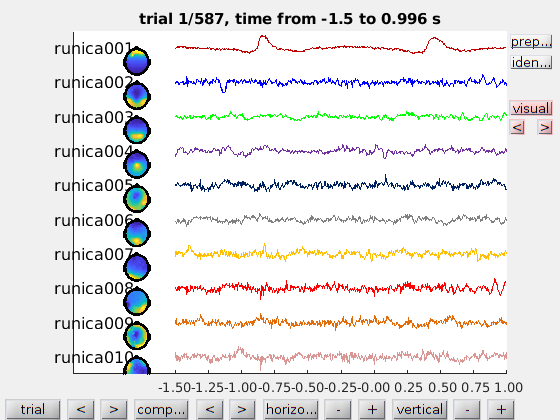

Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.

the call to "ft_databrowser" took 2 seconds and required the additional allocation of an estimated 46 MB


cfg = [];
cfg.layout = 'biosemi128.lay'; 
cfg.viewmode = 'component';
cfg.continuous='no';
cfg.component = 1:10;
cfg.allowoverlap='yes';
ft_databrowser(cfg, ICs)

Remove component 1 which corresponds to the eye blink (16 because of slow drift and 39 because artefacts are present)

cfg=struct('component',[1 16 39], 'updatesens', 'no');
data_ICA = ft_rejectcomponent(cfg, ICs, data_no_bad_ch);

baseline correcting data 
removing 3 components
keeping 106 components
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 5 MB
processing trials
processing trial 587 from 587

not applying the backprojection matrix to the elec structure
the call to "ft_rejectcomponent" took 1 seconds and required the additional allocation of an estimated 312 MB


Compare the EEG before and after the rejection of the component

cfg = [];
cfg.layout = 'biosemi128.lay'; 
cfg.viewmode = 'vertical';
cfg.channel = {'all', '-A1'};
cfg.ylim = 5*[-1 1];
cfg.continuous='no';
cfg.allowoverlap='yes';
ft_databrowser(cfg, data_no_bad_ch)

the input is raw data with 110 channels and 587 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.

the call to "ft_databrowser" took 1 seconds and required the additional allocation of an estimated 20 MB


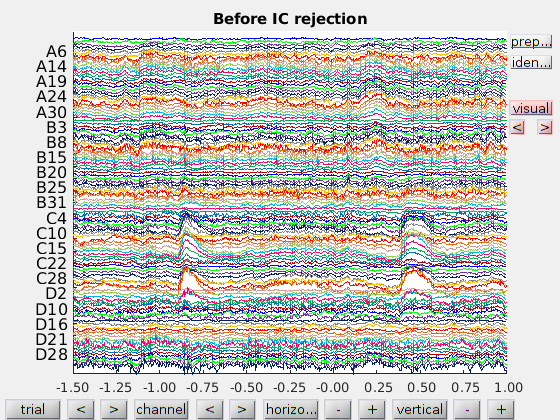

title('Before IC rejection')

ft_databrowser(cfg, data_ICA)

the input is raw data with 110 channels and 587 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.

the call to "ft_databrowser" took 2 seconds and required the additional allocation of an estimated 26 MB


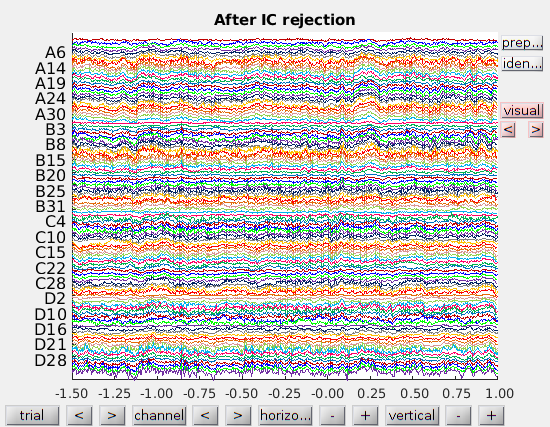

title('After IC rejection')

### Interpolate bad channels

#### Find the neighbour channels

Find the neighbouring channels anf plot them

cfg = struct('channel','all','method','triangulation');
neighbours = ft_prepare_neighbours(cfg, data_seg);

using electrodes specified in the data
there are on average 7.8 neighbours per channel
the call to "ft_prepare_neighbours" took 0 seconds and required the additional allocation of an estimated 2 MB


using electrodes specified in the configuration


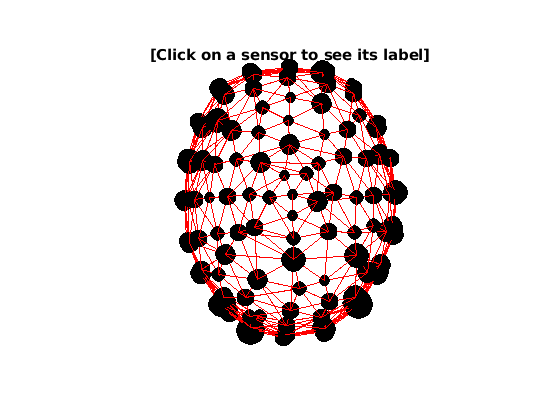

the call to "ft_neighbourplot" took 2 seconds and required the additional allocation of an estimated 14 MB



cfg=struct('neighbours',neighbours,'elec',data_seg.elec);
ft_neighbourplot(cfg)

#### Interpolate the bad channels

Interpolate the bad channels using the traces of the neighbouring channels

cfg = [];
cfg.badchannel=bad_channels;
cfg.method='spline';
cfg.neighbours=neighbours;
data_interp = ft_channelrepair(cfg,data_ICA);

the input is raw data with 110 channels and 587 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
assuming that the data is EEG, use cfg.senstype to overrule this
using electrodes specified in the data
There are 0 bad channels
There are 19 missing channels
Spherical spline and surface Laplacian interpolation will treat bad and missing channels the same. Missing channels will be concatenated at the end of your data structure.
Checking spherical fit... perfect spherical fit (residual: -0.2%)
computing weight matrix... done!

interpolating channels for 587 trials .....................................................................................................................................................................................................................................................................................................................................................................................

reset the original order of the channels if changed

orig_labels=data_seg.label;
if ~all(strcmp(data_interp.label, orig_labels))
    [~, idx] = ismember(orig_labels,data_interp.label);
    data_interp.label = data_interp.label(idx);
    data_interp.trial = cellfun(@(trl) trl(idx,:), data_interp.trial, 'uni', 0);
end

visualise the final result

cfg=[];
cfg.viewmode='vertical';
cfg.ylim = 5*[-1 1];
cfg.allowoverlap='yes';
ft_databrowser(cfg,data_seg);

the input is raw data with 128 channels and 587 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.

the call to "ft_databrowser" took 2 seconds and required the additional allocation of an estimated 13 MB


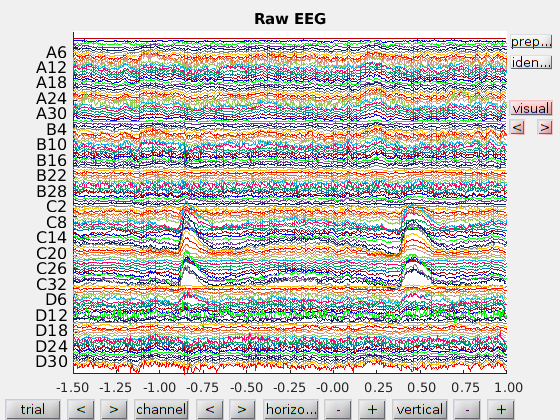

title('Raw EEG')

ft_databrowser(cfg,data_interp);

the input is raw data with 128 channels and 587 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.

the call to "ft_databrowser" took 1 seconds and required the additional allocation of an estimated 14 MB


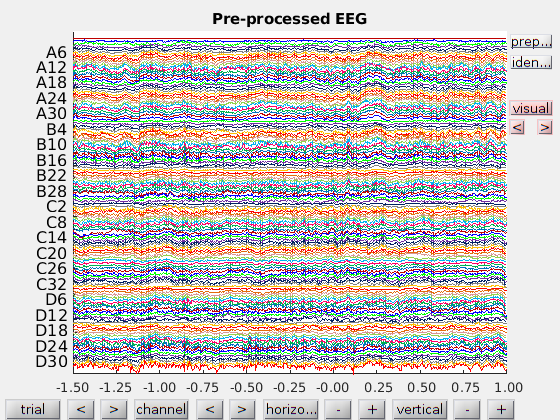

title('Pre-processed EEG')

Re-reference to the average reference

cfg = struct('reref','yes','refchannel','all','method','avg');
data_reref = ft_preprocessing(cfg, data_interp);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 587 from 587

the call to "ft_preprocessing" took 1 seconds and required the additional allocation of an estimated 31 MB


## MRI preprocessing

### Initialisation

sub_id = sprintf('sub-%02d',sub_number);

cmp_preproc_folder=fullfile(BIDS_folder,'derivatives','cmp');
mri_preproc_folder=fullfile(BIDS_folder,'derivatives','mri_preprocessing');
eeg_preproc_folder=fullfile(BIDS_folder,'derivatives','eeg_preprocessing');
mri_filename = fullfile(cmp_preproc_folder, sub_id,'anat', [sub_id,'_desc-head_T1w.nii.gz']); % defaced mri file
GM_filename=fullfile(eeg_preproc_folder,sub_id,'anat',[sub_id,'_label-GM_dseg.nii.gz']); %gray matter map
atlas_filename=fullfile(cmp_preproc_folder,sub_id,'anat',[sub_id,'_atlas-L2018_res-scale1_dseg.nii.gz']);  % atlas file
% hdmdl_filename = fullfile(mri_preproc_folder, sub_id,'anat',[sub_id '_space-individual_desc-reslice_headmodel.mat']); % headmodel created by mri_preprocessing.m script
% srcmdl_filename = fullfile(mri_preproc_folder, sub_id,'anat',[sub_id '_space-individual_desc-reslice_sourcemodel.mat']); % headmodel created by mri_preprocessing.m script
hdmdl_filename = 'headmodel.mat'; % defaced mri file
srcmdl_filename = 'sourcemodel.mat'; % defaced mri file

% Tell Datalad to allow files to be modified
if exist(mri_preproc_folder, 'dir')
    [status,cmdout] = system('datalad unlock -d '+convertCharsToStrings(BIDS_folder)+' '+ convertCharsToStrings(mri_preproc_folder));
    sprintf(cmdout)
end


ans =

  1×0 empty char array



Load the defaced MRI, Atlas and Gray Matter mask

% read defaced MRI file
[mri_fname, temp_folder] = decompress_mri(mri_filename);
mri = ft_read_mri(mri_fname);

the coordinate system appears to be 'scanras'


mri.coordsys = 'ras'; % we suppose that the coord sys is ras
delete(mri_fname);    rmdir(temp_folder);

% Read gray matter MRI file
[gray_fname, temp_folder] = decompress_mri(GM_filename);
gray = ft_read_mri(gray_fname);

the coordinate system appears to be 'scanras'


gray.coordsys = 'ras'; % we suppose that the coord sys is ras
delete(gray_fname);     rmdir(temp_folder);

% Read ATLAS file
[atlas_fname, temp_folder] = decompress_mri(atlas_filename);
atlas = ft_read_mri(atlas_fname);

the coordinate system appears to be 'scanras'


atlas.coordsys = 'ras'; % we suppose that the coord sys is ras
delete(atlas_fname); rmdir(temp_folder);

ROI2remove=[35:39,76:80, 83];
mask=ismember(atlas.anatomy,ROI2remove);
atlas.anatomy(mask) = 0;

Display the three MRI

the input is volume data with dimensions [221 276 221]
scaling anatomy to [0 1]
not plotting functional data
not applying a mask on the functional data
not using an atlas
not using a region-of-interest


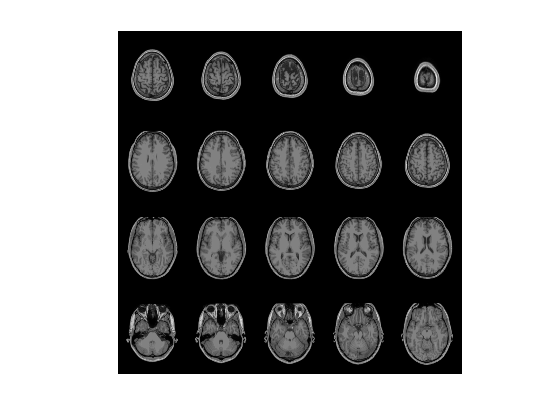

scaling anatomy
the call to "ft_sourceplot" took 0 seconds and required the additional allocation of an estimated 117 MB


cfg = struct('method', 'slice', 'slicerange', [85 200]);
ft_sourceplot(cfg, mri)

the input is volume data with dimensions [221 276 221]
scaling anatomy to [0 1]
not plotting functional data
not applying a mask on the functional data
not using an atlas
not using a region-of-interest


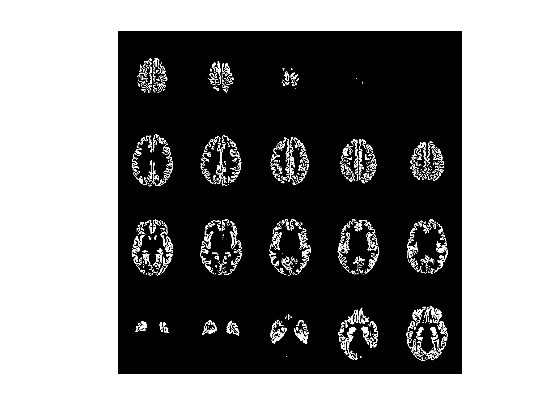

scaling anatomy
the call to "ft_sourceplot" took 0 seconds and required the additional allocation of an estimated 131 MB


ft_sourceplot(cfg, gray)

the input is volume data with dimensions [221 276 221]
scaling anatomy to [0 1]
not applying a mask on the functional data
not using an atlas
not using a region-of-interest


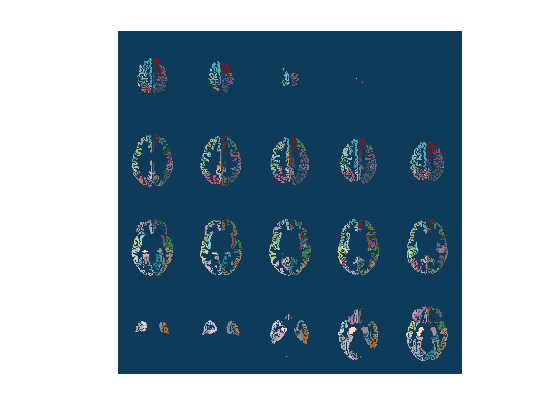

scaling anatomy
the call to "ft_sourceplot" took 0 seconds and required the additional allocation of an estimated 122 MB


cfg.funparameter = 'anatomy';
cfg.funcolormap = 'tab20';
cfg.colorbar = 'off';
ft_sourceplot(cfg, atlas)

### Head model

segment the MRI

% cfg           = [];
% cfg.output = {'brain', 'skull', 'scalp'}; % if MRI is not defaced, simply segment {'brain', 'skull', 'scalp'};
% segmentedmri  = ft_volumesegment(cfg, mri);

little trick applied here to recreate a bit of the forehead

% segmentedmri.scalp = (segmentedmri.scalp | ...
%     imdilate(segmentedmri.skull, strel('sphere',10))) & (~segmentedmri.skull &  ~ segmentedmri.brain);

Remove the neck

% I = find(segmentedmri.skull);
% [~,~,z] = ind2sub(segmentedmri.dim, I);
% [zmin] = min(z);
% segmentedmri.scalp(:,:, 1:zmin-10) = 0;

create surfaces (mesh at tissues interfaces)

% cfg=[];
% cfg.tissue={'brain','skull','scalp'};
% cfg.numvertices=[3000,2000,1000];
% mesh=ft_prepare_mesh(cfg,segmentedmri);

create a volume conduction model

% cfg=[];
% cfg.method='concentricspheres';
% headmodel  = ft_prepare_headmodel(cfg, mesh);

Load the precomputed head model

load(hdmdl_filename, 'headmodel', 'mesh')

Plot the meshes

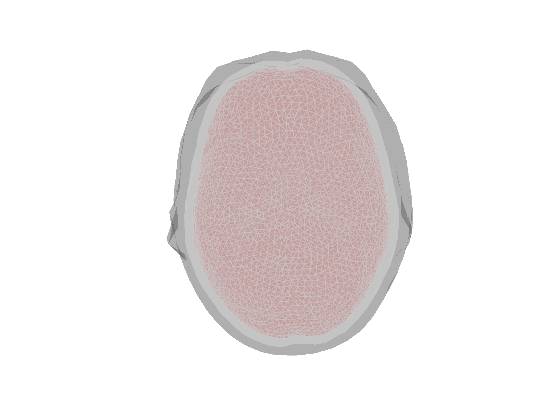

figure
ft_plot_mesh(mesh(1), 'facecolor',[0.9 0.2 0.2], 'facealpha', 0.3, 'edgecolor', [1 1 1], 'edgealpha', 0.05);
hold on;
ft_plot_mesh(mesh(2),'edgecolor','none','facealpha',0.4);
ft_plot_mesh(mesh(3),'edgecolor','none','facecolor',0.4*[1 1 1],'facealpha', 0.3);

Display the three concentric spheres

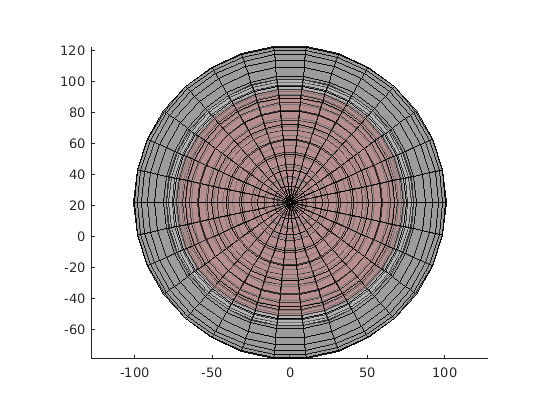

[X,Y,Z] = sphere(30);
sphr = cat(3,X,Y,Z);

R = headmodel.r(1:3);
O = headmodel.o;
clr = [0.9 0.2 0.2; 1 1 1; 0.4 0.4 0.4];

figure;
hold on
for k = 1:3
    curr_sphr = R(k)*sphr + permute(O, [1 3 2]);
    surf(curr_sphr(:,:,1),curr_sphr(:,:,2),curr_sphr(:,:,3), 'EdgeColor'...
        ,'k', 'EdgeAlpha',0.3,'FaceColor', clr(k,:), 'FaceAlpha', 0.4)
end
axis vis3d equal
plot3(headmodel.o(1),headmodel.o(2),headmodel.o(3), 'r+', 'MarkerSize',20)

### Source model

remove the ROIs of the Basal Ganglia from GM

% mask=ismember(atlas.anatomy,ROI2remove);
% gray.anatomy(mask)=0;

To have a nicely aligned grid, realigned and reslice the mri to a template

% tmp_mri_filename = fullfile(path2fieldtrip, 'external', 'spm12','toolbox', 'OldNorm', 'T1.nii');
% tmp_mri = ft_read_mri(tmp_mri_filename);
% tmp_mri.coordsys = 'ras';

Co-register the mri to the template

% cfg = [];
% cfg.method = 'spm';
% cfg.spm.regtype = 'rigid';
% cfg.viewresult = 'no';
% [realign] = ft_volumerealign(cfg, mri, tmp_mri);

apply the same transformation to the gray matter map

% realign_gray = gray;
% realign_gray.transform = realign.transform;

apply 1 mm reslicing

% cfg=struct('method','cubic','resolution',1,'dim',250*[1 1 1]);
% realign_reslice_GM = ft_volumereslice(cfg, realign_gray);
% clear realign_gray

create source model restricted to gray matter

% cfg=struct('resolution',6,'unit','mm','tight','yes','mri',realign_reslice_GM);
% sourcemodel = ft_prepare_sourcemodel(cfg);

transform the coordinate of the source model back to the original mri space (they are currently in the space of the template)

% T_mat = realign.transformorig/realign.transform;
% [sourcemodel.pos]= ft_warp_apply(T_mat, sourcemodel.pos, 'homogeneous');

Load the precomputed source model (sources are positioned in the gray matter except the basal ganglia )

load(srcmdl_filename, 'sourcemodel')

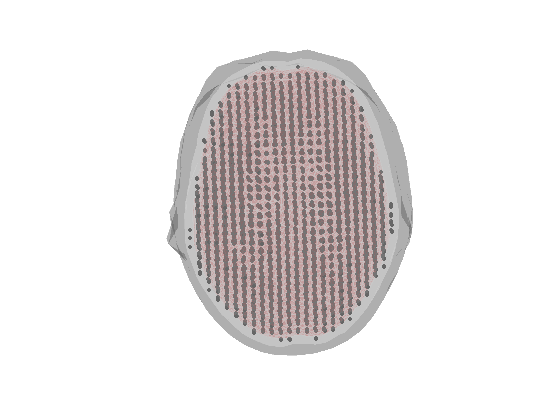

figure
ft_plot_mesh(mesh(1), 'facecolor',[0.9 0.2 0.2], 'facealpha', 0.3, 'edgecolor', [1 1 1], 'edgealpha', 0.05);
hold on;
ft_plot_mesh(mesh(2),'edgecolor','none','facealpha',0.4);
ft_plot_mesh(mesh(3),'edgecolor','none','facecolor',0.4*[1 1 1],'facealpha', 0.3);
ft_plot_mesh(sourcemodel.pos(sourcemodel.inside,:),'vertexcolor', 'k');

finally, verify that the electrode are aligned to the MRI

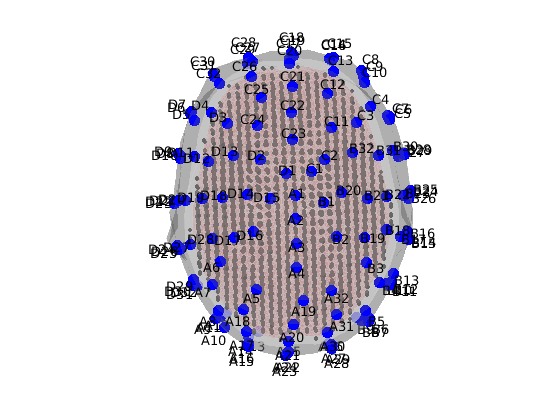

ft_plot_sens(data_reref.elec, 'style', '.b', 'label', 'label')

## Inverse Solution

### Leadfield matrix (forward model) and Inverse Operator

estimate the leadfield

cfg         = [];
cfg.elec    = data_reref.elec;   % sensor information
cfg.sourcemodel    = sourcemodel;   % source points
cfg.headmodel = headmodel;   % volume conduction model
leadfield   = ft_prepare_leadfield(cfg);

using electrodes specified in the configuration
creating sourcemodel based on user specified dipole positions
using electrodes specified in the configuration
5583 dipoles inside, 10545 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 0 seconds and required the additional allocation of an estimated 1 MB
computing leadfield
computing leadfield 5583/5583

the call to "ft_prepare_leadfield" took 144 seconds and required the additional allocation of an estimated 31 MB


calculate covariance matrix from baseline

cfg = [];
cfg.covariance = 'yes';
cfg.covariancewindow = [-.1 0]; %calculate cov on timepoints before the zero-time point in the trials
data = ft_timelockanalysis(cfg, data_reref);

the input is raw data with 128 channels and 587 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 16 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_timelockanalysis" took 2 seconds and required the additional allocation of an estimated 390 MB


estimate the inverse operator

dat = []; % we only want the filter for now
hdmodel = []; % the headmodel is only used when isinside not present in leadfield and if sourcemodel does not have leadfield
elec = []; % the elec structure is only need if leadfield not present which is not hte case here

% inverse_operator = ft_inverse_mne(leadfield, elec, hdmodel, dat, ...
%     'noisecov', data.cov, 'keepfilter', 'yes', 'prewhiten',...
%     'yes','scalesourcecov','yes',...
%     'lambda', 0.5);

% inverse_operator = ft_inverse_sloreta(leadfield, elec, hdmodel, dat, data.cov, 'lambda', 0.05);

% inverse_operator = ft_inverse_lcmv(leadfield, elec, hdmodel, dat, ...
%     data.cov, 'keepfilter', 'yes','lambda', 0.05,'weightnorm','unitnoisegain','projectnoise','yes');

% inverse_operator = ft_inverse_dics(leadfield, elec, hdmodel, dat, ...
%     data.cov, 'keepfilter', 'yes','lambda', 0.05,'weightnorm','unitnoisegain','projectnoise','yes');


inverse_operator = ft_inverse_eloreta(leadfield, elec, hdmodel, dat, ...
    data.cov, 'keepfilter', 'yes','lambda', 0.05);

using precomputed leadfields
    0.9568

    0.7759

    0.5352

    0.3208

    0.1765

    0.0927

    0.0475

    0.0241

    0.0121

    0.0061

    0.0030

    0.0015

   7.6112e-04

   3.8064e-04

   1.9034e-04

   9.5173e-05

   4.7588e-05

   2.3794e-05

   1.1897e-05

   5.9486e-06

   2.9743e-06



cfg = [];
cfg.trials = find(data_reref.trialinfo == 1);
avg_FAC = ft_timelockanalysis(cfg, data_reref);

the input is raw data with 128 channels and 587 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_timelockanalysis" took 1 seconds and required the additional allocation of an estimated 180 MB


filter = cat(1,inverse_operator.filter{:});
source_data=sourcemodel;
source_data.pow = zeros(size(inverse_operator.inside));
% dnoise = diag(diag(1./blkdiag(inverse_operator.noisecov{:})));
t_of_int = avg_FAC.time;

t_idx = find(t_of_int >= 0.147, 1, 'first');

% src = dnoise*filter*avg_FAC.avg(:,t_idx);
src = filter*avg_FAC.avg(:,t_idx);
src = reshape(src,3,[]);
pow_src = sum(src.^2);
% pow_src = sum(src.^2)./inverse_operator.noise(inverse_operator.inside)';


source_data.pow(source_data.inside) = pow_src';
cfg = struct('interpmethod', 'spline', 'parameter', 'pow', 'verbose', 'off');
[interp] = ft_sourceinterpolate(cfg, source_data, mri);

the input is volume data with dimensions [221 276 221]
the input is source data with 16128 brainordinates on a [24 32 21] grid
selecting subvolume of 22.8%
interpolatininterpolating 100.0
reslicing and interpolating pow
interpolatinterpolating 100.0
the call to "ft_sourceinterpolate" took 2 seconds and required the additional allocation of an estimated 752 MB


the input is source data with 16128 brainordinates on a [24 32 21] grid
the input is volume data with dimensions [221 276 221]
the input is source data with 16128 brainordinates on a [24 32 21] grid
selecting subvolume of 22.8%
interpolating
interpolating 100.0
reslicing and interpolating pow
interpolating
interpolating 100.0
the call to "ft_sourceinterpolate" took 2 seconds and required the additional allocation of an estimated 618 MB
scaling anatomy to [0 1]
not using an atlas
not using a region-of-interest


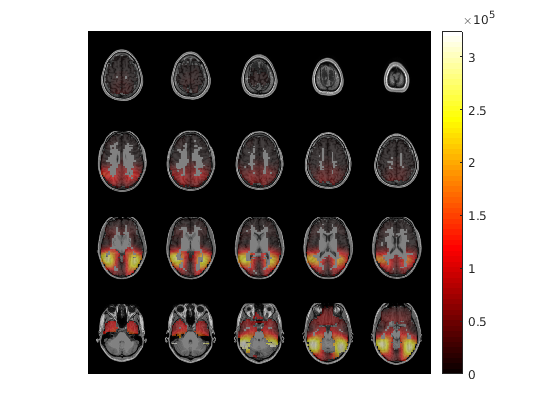

scaling anatomy
the call to "ft_sourceplot" took 3 seconds and required the additional allocation of an estimated 618 MB


cfg = struct('method', 'slice', 'slicerange', [85 200], 'funparameter', 'pow', 'funcolorlim', [0 max(pow_src(:))]);
% cfg = struct('method', 'slice', 'slicedim', 1, 'funparameter', 'pow', 'funcolorlim', [0 max(pow_src(:))]);
ft_sourceplot(cfg, source_data, mri);

## ROI time course

Now project the cleaned scalp EEG traces in the source space and apply the SVD to have a single traces for each ROI

Assign each point source to an ROIs

% Tbl_idx2label = readtable('Lausanne_atlas_label.tsv','FileType',...
%             'text', 'Delimiter', '\t');
% 
% mask=ismember(atlas.anatomy,ROI2remove);
% atlas.anatomy(mask) = 0;
% 
% [src_label, ROIs_elec]= ...
%     assigned_label2source_points(inverse_operator, atlas, Tbl_idx2label);

% ROIs_lbl = unique(src_label(~strcmp(src_label,'Outside')), 'stable');
% [bln, idx] = ismember(Tbl_idx2label.abbreviation,ROIs_lbl);
% ROIs_lbl = ROIs_lbl(nonzeros(idx));
% 
% n_ROIs = length(ROIs_lbl);
% filters = inverse_operator.filter;
% Fs = data_reref.fsample;
% 
% [n_channels, n_samples] = size(data_reref.trial{1}); % only works if trials have the same length
% n_trials = length(data_reref.trial);
% time_courses = cat(2, data_reref.trial{:});
% 
% ROI_traces = zeros(n_ROIs, n_samples*n_trials);
% 
% % parfor uses the parallel toolbox to parallelise the loop, change to for if this toolbox is not available
% parfor ROI_id = 1:n_ROIs
%     curr_ROI_bln = strcmp(src_label, ROIs_lbl{ROI_id});
%     curr_filters = filters(curr_ROI_bln);
%     curr_filters = cat(1,curr_filters{:});
%     
%     ESI_tmp = time_courses.'*curr_filters.'; % Inverse space transformation
%     [ROI_traces(ROI_id,:),S,V] = svds(ESI_tmp,1);
%     ROI_traces(ROI_id,:) = S*ROI_traces(ROI_id,:);
% end
% 
% %% recreate a Fieldtrip data structure and store it
% ROI_data.trial = ROI_traces;
% ROI_data.trial = mat2cell(ROI_data.trial, n_ROIs, n_samples*ones(1,n_trials));
% ROI_data.elec = ROIs_elec;
% ROI_data.trialinfo = data_reref.trialinfo;
% ROI_data.label = ROIs_lbl;
% ROI_data.fsample = data_reref.fsample;
% ROI_data.time = data_reref.time;
% ROI_data.sampleinfo = data_reref.sampleinfo;

Load previously computed ROi traces

load(fullfile(BIDS_folder,'derivatives','source_modelling',sub_id,'eeg','ROI_data.mat'), 'ROI_data');

Average the ROI time-series for the face and scrambled condition

cfg = [];
cfg.trials = find(ROI_data.trialinfo == 1);
avg_ROI_FAC = ft_timelockanalysis(cfg, ROI_data);

the input is raw data with 72 channels and 587 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1721 MB
the call to "ft_timelockanalysis" took 18446744066510 seconds and required the additional allocation of an estimated 0 MB


cfg = [];
cfg.trials = find(ROI_data.trialinfo == 0);
avg_ROI_SRC = ft_timelockanalysis(cfg, ROI_data);

the input is raw data with 72 channels and 587 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1706 MB
the call to "ft_timelockanalysis" took 1 seconds and required the additional allocation of an estimated 1706 MB


Get a mesh for each ROI

Tbl_idx2label = readtable('Lausanne_atlas_label.tsv','FileType','text','Delimiter','\t');
n_ROIs = length(ROI_data.label);
for id_ROI = 1:n_ROIs
bln = strcmp(Tbl_idx2label.abbreviation, ROI_data.label{id_ROI});
fv(id_ROI) = isosurface(smooth3(atlas.anatomy == Tbl_idx2label.index(bln), 'gaussian',5*[1 1 1]),0.5);
end

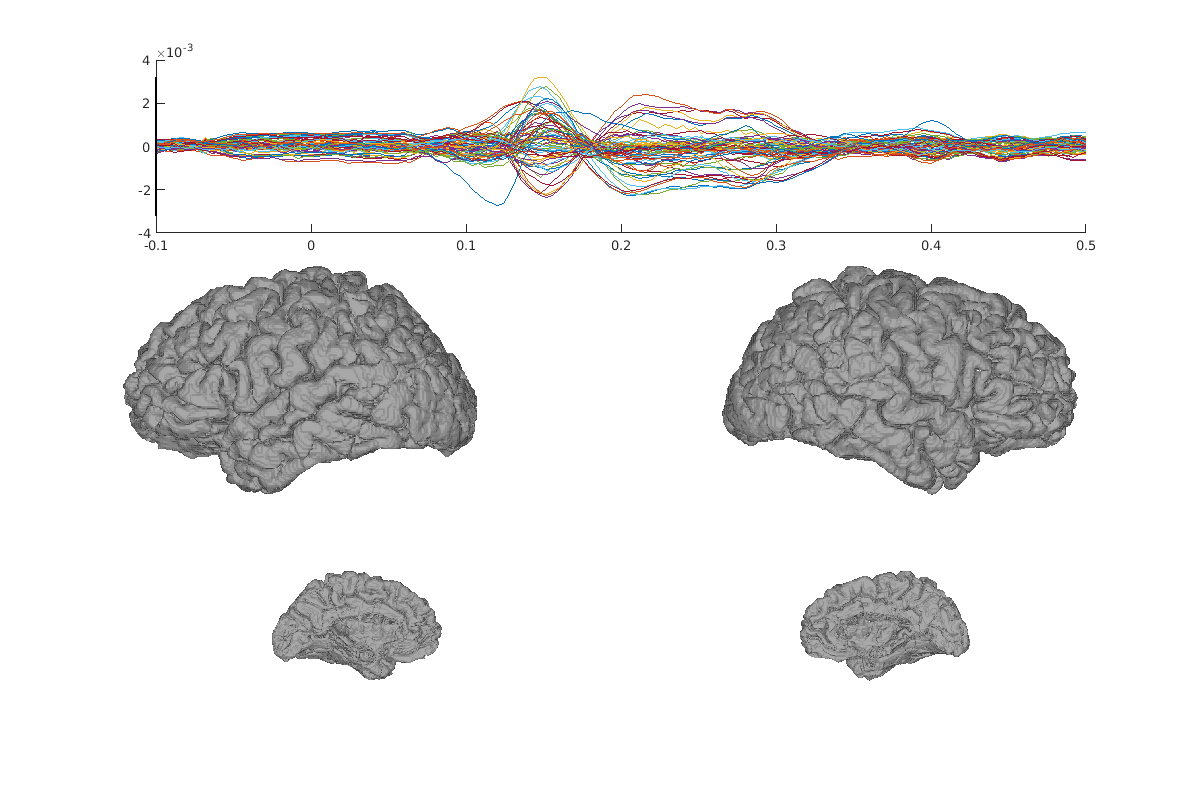

normcoef = max(abs(avg_ROI_FAC.avg(:)));
figure('Color','w', 'Position', [120 120 1200 800]);
ax(1) = subplot(3,1,1);
hold on;
plot(avg_ROI_FAC.time, avg_ROI_FAC.avg)
vline = plot(-0.1*[1 1], normcoef*[-1 1],'k', 'LineWidth',2);
xlim([-0.1 0.5])
ax(2) = subplot(3,2,3);
p(:,1) = arrayfun(@(fv) patch(fv, 'EdgeColor', 'None', 'FaceColor', 0.6*[1 1 1]), fv(end/2+1:end));
view([0 0])
ax(3) = subplot(3,2,4);
p(:,2) = arrayfun(@(fv) patch(fv, 'EdgeColor', 'None', 'FaceColor', 0.6*[1 1 1]), fv(1:end/2));
view([180 0])
ax(4) = subplot(3,2,5);
p(:,3) = arrayfun(@(fv) patch(fv, 'EdgeColor', 'None', 'FaceColor', 0.6*[1 1 1]), fv(end/2+1:end));
view([180 0])
ax(5) = subplot(3,2,6);
p(:,4) = arrayfun(@(fv) patch(fv, 'EdgeColor', 'None', 'FaceColor', 0.6*[1 1 1]), fv(1:end/2));
view([0 0])
axis(ax(2:end), 'vis3d', 'equal', 'off')
material(ax(2:end), 'dull')
arrayfun(@(axx) camlight(axx, 'headlight'), ax(2:end));
ax(2).Position = [0.025 0.3 0.45 0.45];
ax(3).Position = [0.525 0.3 0.45 0.45];
ax(4).Position = [0.025 -0.05 0.45 0.45];
ax(5).Position = [0.525 -0.05 0.45 0.45];
set(ax(2:5), 'XDir', 'reverse')

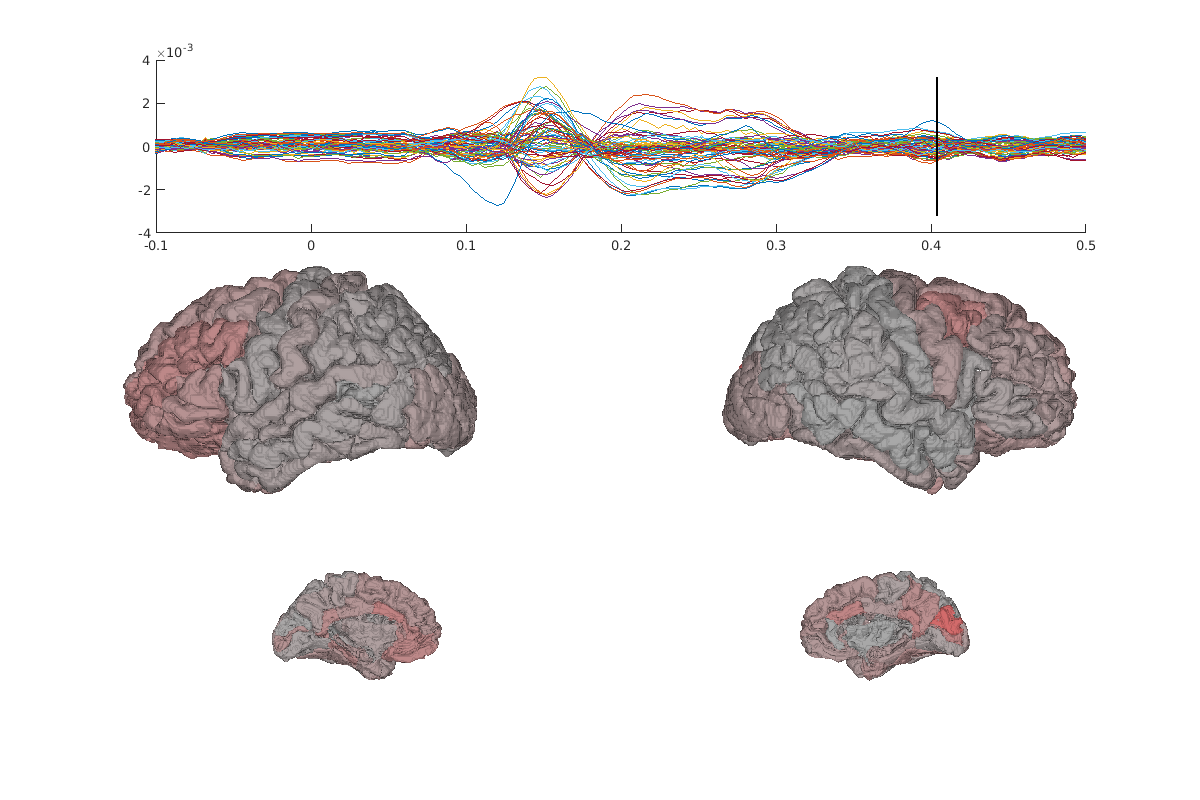

colour = [linspace(0.6,1, 256)', linspace(0.6,0, 256)' linspace(0.6,0, 256)'];
selected_time = [find(ROI_data.time{1} > -0.1, 1, 'first'), find(ROI_data.time{1} > 0, 1, 'first'),...
    find(ROI_data.time{1} > 0.1, 1, 'first'), find(ROI_data.time{1} > 0.147, 1, 'first'), find(ROI_data.time{1} > 0.2, 1, 'first'),...
    find(ROI_data.time{1} > 0.4, 1, 'first')];


for ind_t = selected_time
    vline.XData = [1 1]*avg_ROI_FAC.time(ind_t);
    curr_amp = abs(avg_ROI_FAC.avg(:,ind_t));
    idx_clr = ceil(curr_amp*256/normcoef);
    for id_ROI = 1:length(ROI_data.label)
        if id_ROI <= n_ROIs/2
            [p(id_ROI,[1 3]).FaceColor] = deal(colour(idx_clr(id_ROI),:));
        else
            [p(id_ROI-n_ROIs/2,[2 4]).FaceColor] = deal(colour(idx_clr(id_ROI),:));
        end
    end
    drawnow
    pause(0.2)
end

cfg = [];
cfg.layout = ft_prepare_layout(struct('layout', 'ordered', 'columns', 9, 'rows', 8), avg_ROI_SRC)

the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB


cfg = struct with fields:
    layout: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB


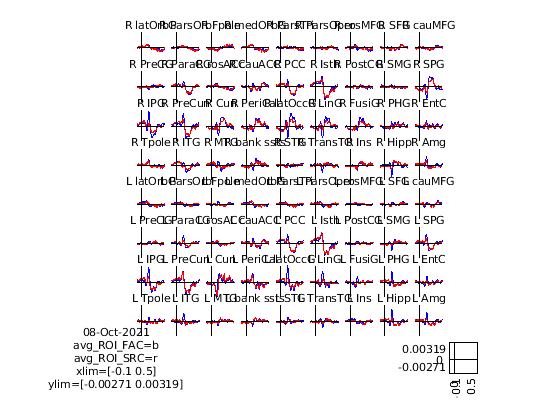

the call to "ft_multiplotER" took 2 seconds and required the additional allocation of an estimated 1 MB


cfg.xlim = [-0.1, 0.5];
cfg.showlabels = 'yes';
ft_multiplotER(cfg,avg_ROI_FAC,avg_ROI_SRC);